clear
clc
close all
format long

% System matrices from physics-based model
A = [-7.017 7.017 0; 2.248 -2.248+3.32*10^(-5) 3.32*10^(-5); 0 2.496*10^(-4) -2.496*10^(-4)];
B = [24.938; 0; 0];
C = eye(3);
D = zeros(3,1);

% Weighting factors
Q = diag([0.1 0.1 10]);
R = [0.1];

%Desired equilibrium states for the system.
xd = [393.15; 393.15; 393.15];

%Initial conditions
x0 = [295.15; 295.15; 295.15];

% clear
% clc
% close all
% format long
% System matrices from system identification
% A = [-0.000636]
% B = [4.738*10^(-6)]
% C = 1;
% D = zeros(1,1);
% 
% Weighting factors
% Q = diag([0.1]);
% R = [0.001];
% 
% % %Desired equilibrium states for the system.
% xd = [120];

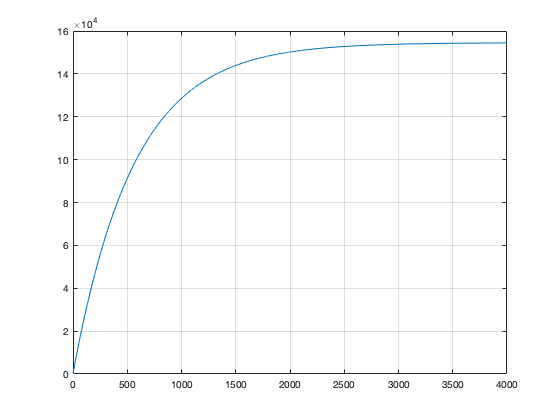


%LQR solution
[K, S, E] = lqr(A, B, Q, R);

% xdot = Ax + B u =>xdot = (A-BK)x + K xd
% u = -K(x - xd) y = Cx
%Close loop xdot = Ax + B K (xd-x)
plant = ss(A-B*K, B*K*xd, C, D);


tfinal = 4000;
time_total = 0:0.1:tfinal;

closed_loop_input = [xd(1)*ones(size(time_total))];

[output_closed_loop,time_closed_loop,state_closed_loop] = lsim(plant, closed_loop_input,time_total, x0);


figure(1);
plot(time_total,state_closed_loop(:,3))
grid on;